# Tarea: Análisis Numérico

## Profesor: Miriam Sosa Díaz

## Ayudante: Andrea Fernanda Rodríguez Rojas

#### Tema: Health-Scientific-Computing. Interpolación

**7.1** *(a)* Escriba una rutina que utilice la regla de Horner para evaluar un polinomio $$p(x)$$ dado su grado *n*, un array *x* que contiene sus coeficientes, y el valor *t* de la variable independiente en que debe ser evaluado.

%% Ejemplo de prueba

% Polinomio: p(t) = 2t^3 - 6t^2 + 2t - 1
n = 3;
x = [2, -6, 2, -1];
t = 3;

p = horner(n, x, t);
fprintf('p(%g) = %g\n', t, p)

p(3) = 5


`(b)`` Agregue opciones a su rutina para evaluar la derivada `$p^{\prime } (t)$` o la integral `$\int_a^b p(t)dt$`, dados ``a`` y ``b``.`

%% (b) Evaluación con opciones: valor, derivada, integral

% Polinomio: p(t) = 2t^3 - 6t^2 + 2t - 1
n = 3;
x = [2, -6, 2, -1];
t = 3;
a = 0;
b = 3;

fprintf('p(%g)        = %g\n', t, horner_ext(n, x, t, 'valor'))

p(3)        = 5


fprintf("p'(%g)       = %g\n", t, horner_ext(n, x, t, 'derivada'))

p'(3)       = 20


fprintf('integral     = %g\n', horner_ext(n, x, t, 'integral', a, b))

integral     = -7.5


function resultado = horner(n, x, t)
    % Evalúa el polinomio p(t) usando la regla de Horner
    % Entradas:
    %   n : grado del polinomio
    %   x : array de coeficientes [x_n, x_{n-1}, ..., x_1, x_0]
    %   t : valor donde se evalúa el polinomio
    % Salida:
    %   resultado : valor de p(t)

    resultado = x(1);
    for i = 2:n+1
        resultado = resultado * t + x(i);
    end
end

function resultado = horner_ext(n, x, t, opcion, a, b)
    % Extiende la regla de Horner para evaluar p(t), p'(t) o integral
    % Entradas:
    %   n      : grado del polinomio
    %   x      : coeficientes [x_n, ..., x_0]
    %   t      : punto de evaluación
    %   opcion : 'valor', 'derivada', o 'integral'
    %   a, b   : límites de integración (solo para 'integral')
    % Salida:
    %   resultado : valor según la opción elegida

    switch opcion
        case 'valor'
            resultado = horner(n, x, t);

        case 'derivada'
            % Coeficientes de p'(t) por diferenciación
            dx = zeros(1, n);
            for i = 1:n
                dx(i) = (n - i + 1) * x(i);
            end
            resultado = horner(n-1, dx, t);

        case 'integral'
            % Coeficientes de la antiderivada P(t)
            ix = zeros(1, n+2);
            for i = 1:n+1
                ix(i) = x(i) / (n - i + 2);
            end
            resultado = horner(n+1, ix, b) - horner(n+1, ix, a);
    end
end

`7.2 ``(a)``  Escriba una rutina para calcular el Interpolante polinomial de Newton para un conjunto dado de puntos de datos, y una segunda rutina para evaluar el interpolante de Newton en un valor de argumento dado utilizando la regla de Horner.`

`(b)`` Escriba una rutina para calcular el nuevo Interpolante polinomial de Newton cuando un se agrega un nuevo punto de datos.`

`(c)`` Si su lenguaje de programación admite recursión, escriba una rutina recursiva que implemente la parte ``(a)`` llamando a su rutina para la parte ``(b)`` recursivamente. Compare su rendimiento con la de su implementación original.`

Puntos de datos de prueba (compartidos por todas las secciones)

Usamos la función f(x) = 1/(1 + x^2) muestreada en 5 nodos igualmente espaciados.

x = [-2, -1, 0, 1, 2];          % nodos de interpolación
y = 1 ./ (1 + x.^2);            % valores: f(x) = 1/(1+x²)

fprintf('Nodos de interpolación:\n');

Nodos de interpolación:


fprintf('  x = [%s]\n', num2str(x));

  x = [-2 -1  0  1  2]


fprintf('  y = [%s]\n\n', num2str(y, '%.4f '));

  y = [0.2000 0.5000 1.0000 0.5000 0.2000]



═══════════════════════════════════════════════════════════════

**7.2** PARTE (a) — Cálculo y evaluación del interpolante de Newton

═══════════════════════════════════════════════════════════════

Se calculan las diferencias divididas (coeficientes de Newton) y se

evalúa el polinomio en un punto usando la regla de Horner.

%--- Calcular coeficientes ---
c = newton_coeficientes(x, y);

fprintf('=== PARTE (a) ===\n');

=== PARTE (a) ===


fprintf('Coeficientes de diferencias divididas de Newton:\n');

Coeficientes de diferencias divididas de Newton:


for k = 1:length(c)
    fprintf('  c(%d) = %10.6f\n', k, c(k));
end

  c(1) =   0.200000
  c(2) =   0.300000
  c(3) =   0.100000
  c(4) =  -0.200000
  c(5) =   0.100000


%--- Evaluar en varios puntos ---
x_eval = linspace(-2, 2, 200);
p_eval = arrayfun(@(t) horner_newton(c, x, t), x_eval);
f_real = 1 ./ (1 + x_eval.^2);

% Evaluación en un punto específico
x_test = 0.5;
p_test = horner_newton(c, x, x_test);
fprintf('\nEvaluación en x = %.2f:\n', x_test);


Evaluación en x = 0.50:


fprintf('  P(%.2f) = %.8f\n', x_test, p_test);

  P(0.50) = 0.85625000


fprintf('  f(%.2f) = %.8f\n', x_test, 1/(1 + x_test^2));

  f(0.50) = 0.80000000


fprintf('  Error   = %.2e\n\n', abs(p_test - 1/(1+x_test^2)));

  Error   = 5.62e-02



% --- Gráfica ---
figure(1); clf;
plot(x_eval, f_real, 'b-', 'LineWidth', 2, 'DisplayName', 'f(x) = 1/(1+x²)');
hold on;
plot(x_eval, p_eval, 'r--', 'LineWidth', 1.8, 'DisplayName', 'Interpolante P(x)');
plot(x, y, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k', 'DisplayName', 'Nodos');
xlabel('x'); ylabel('y');
title('Parte (a): Interpolante de Newton con Regla de Horner');
legend('Location', 'best'); grid on;

═══════════════════════════════════════════════════════════════

**7.2** PARTE (b) — Agregar un nuevo punto de datos

═══════════════════════════════════════════════════════════════

% Dado el interpolante existente (c, x), se agrega x_nuevo sin recalcular
% todos los coeficientes desde cero.

x_nuevo = 1.5;
y_nuevo = 1 / (1 + x_nuevo^2);

[c_amp, x_amp] = newton_agregar_punto(c, x, x_nuevo, y_nuevo);

fprintf('=== PARTE (b) ===\n');

=== PARTE (b) ===


fprintf('Punto nuevo agregado: (%.2f, %.6f)\n', x_nuevo, y_nuevo);

Punto nuevo agregado: (1.50, 0.307692)


fprintf('Nuevo coeficiente c(%d) = %.8f\n\n', length(c_amp), c_amp(end));

Nuevo coeficiente c(6) = -0.04615385




% Verificar consistencia con recálculo completo
x_full = [x, x_nuevo];
y_full = [y, y_nuevo];
c_full = newton_coeficientes(x_full, y_full);

fprintf('Verificación (recálculo completo vs. actualización incremental):\n');

Verificación (recálculo completo vs. actualización incremental):


fprintf('  %-10s %-18s %-18s %-12s\n', 'Coef.', 'Incremental', 'Completo', 'Diferencia');

  Coef.      Incremental        Completo           Diferencia  


for k = 1:length(c_amp)
    fprintf('  c(%-2d)     %16.10f   %16.10f   %.2e\n', ...
        k, c_amp(k), c_full(k), abs(c_amp(k) - c_full(k)));
end

  c(1 )         0.2000000000       0.2000000000   0.00e+00
  c(2 )         0.3000000000       0.3000000000   0.00e+00
  c(3 )         0.1000000000       0.1000000000   0.00e+00
  c(4 )        -0.2000000000      -0.2000000000   0.00e+00
  c(5 )         0.1000000000       0.1000000000   0.00e+00
  c(6 )        -0.0461538462      -0.0461538462   4.16e-17


% Evaluación comparativa
p_amp  = arrayfun(@(t) horner_newton(c_amp, x_amp, t), x_eval);
p_full = arrayfun(@(t) horner_newton(c_full, x_full, t), x_eval);

figure(2); clf;
plot(x_eval, f_real, 'b-', 'LineWidth', 2, 'DisplayName', 'f(x)');
hold on;
plot(x_eval, p_amp, 'r--', 'LineWidth', 1.8, 'DisplayName', 'P ampliado (incremental)');
plot(x_eval, p_full, 'g:', 'LineWidth', 2.0, 'DisplayName', 'P ampliado (completo)');
plot(x_amp, y_full, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k', 'DisplayName', 'Nodos');
xlabel('x'); ylabel('y');
title('Parte (b): Newton con punto adicional');
legend('Location', 'best'); grid on;

═══════════════════════════════════════════════════════════════

**7.2** PARTE (c) — Implementación recursiva y comparación de rendimiento

═══════════════════════════════════════════════════════════════

% La rutina recursiva construye el interpolante de n puntos llamando
% primero al interpolante de n-1 puntos (parte b) de forma recursiva,
% y luego agrega el n-ésimo punto.

% --- Correctitud ---
c_rec = newton_recursivo(x, y);

fprintf('=== PARTE (c) ===\n');

=== PARTE (c) ===


fprintf('Coeficientes (recursivo vs. iterativo):\n');

Coeficientes (recursivo vs. iterativo):


fprintf('  %-10s %-18s %-18s %-12s\n', 'Coef.', 'Recursivo', 'Iterativo', 'Diferencia');

  Coef.      Recursivo          Iterativo          Diferencia  


for k = 1:length(c)
    fprintf('  c(%-2d)     %16.10f   %16.10f   %.2e\n', ...
        k, c_rec(k), c(k), abs(c_rec(k) - c(k)));
end

  c(1 )         0.2000000000       0.2000000000   0.00e+00
  c(2 )         0.3000000000       0.3000000000   0.00e+00
  c(3 )         0.1000000000       0.1000000000   2.78e-17
  c(4 )        -0.2000000000      -0.2000000000   2.78e-17
  c(5 )         0.1000000000       0.1000000000   1.39e-17



% --- Comparación de rendimiento ---
n_puntos = 5:5:80;              % tamaños de problema
t_iter   = zeros(size(n_puntos));
t_rec    = zeros(size(n_puntos));
n_rep    = 50;                  % repeticiones para promediar

for idx = 1:length(n_puntos)
    n  = n_puntos(idx);
    xi = linspace(-2, 2, n);
    yi = 1 ./ (1 + xi.^2);
    
    % Iterativo
    t0 = tic;
    for r = 1:n_rep
        newton_coeficientes(xi, yi);
    end
    t_iter(idx) = toc(t0) / n_rep;
    
    % Recursivo
    t0 = tic;
    for r = 1:n_rep
        newton_recursivo(xi, yi);
    end
    t_rec(idx) = toc(t0) / n_rep;
end

fprintf('\nComparación de rendimiento (promedio de %d repeticiones):\n', n_rep);


Comparación de rendimiento (promedio de 50 repeticiones):


fprintf('  %-8s %-18s %-18s %-12s\n', 'n', 'Iterativo (s)', 'Recursivo (s)', 'Ratio Rec/Iter');

  n        Iterativo (s)      Recursivo (s)      Ratio Rec/Iter


for idx = 1:length(n_puntos)
    fprintf('  %-8d %-18.6e %-18.6e %-12.2f\n', ...
        n_puntos(idx), t_iter(idx), t_rec(idx), t_rec(idx)/t_iter(idx));
end

  5        4.162000e-05       1.591000e-04       3.82        
  10       4.240000e-06       1.518000e-05       3.58        
  15       4.680000e-06       2.288000e-05       4.89        
  20       6.880000e-06       2.972000e-05       4.32        
  25       1.122000e-05       5.096000e-05       4.54        
  30       2.644000e-05       8.970000e-05       3.39        
  35       1.502000e-05       6.312000e-05       4.20        
  40       1.952000e-05       6.330000e-05       3.24        
  45       5.772000e-05       1.290200e-04       2.24        
  50       2.926000e-05       8.318000e-05       2.84        
  55       4.294000e-05       1.597200e-04       3.72        
  60       6.812000e-05       1.123400e-04       1.65        
  65       1.014800e-04       1.224000e-04       1.21        
  70       5.608000e-05       1.390200e-04       2.48        
  75       7.516000e-05       2.617400e-04       3.48        
  80       7.208000e-05       1.530600e-04       2.12        



figure(3); clf;
semilogy(n_puntos, t_iter, 'b-o', 'LineWidth', 2, 'MarkerSize', 6, ...
    'DisplayName', 'Iterativo');
hold on;
semilogy(n_puntos, t_rec, 'r-s', 'LineWidth', 2, 'MarkerSize', 6, ...
    'DisplayName', 'Recursivo');
xlabel('Número de nodos n'); ylabel('Tiempo promedio (s)');
title('Parte (c): Rendimiento — Iterativo vs. Recursivo');
legend('Location', 'northwest'); grid on;

fprintf('\n--- Análisis ---\n');


--- Análisis ---


fprintf('La versión recursiva es más lenta debido a la sobrecarga de\n');

La versión recursiva es más lenta debido a la sobrecarga de


fprintf('llamadas a función (stack frames) en cada nivel de recursión.\n');

llamadas a función (stack frames) en cada nivel de recursión.


fprintf('Para n grande, el ratio Rec/Iter crece, confirmando que la\n');

Para n grande, el ratio Rec/Iter crece, confirmando que la


fprintf('implementación iterativa es preferible en la práctica.\n');

implementación iterativa es preferible en la práctica.


═══════════════════════════════════════════════════════════════

MODELOS Y FUNCIONES

═══════════════════════════════════════════════════════════════

Función: newton_coeficientes  (Parte a)

% Calcula los coeficientes de diferencias divididas de Newton.
%
% Entrada:
%   x  — vector fila/columna de nodos (n elementos)
%   y  — vector de valores f(x_i)     (n elementos)
% Salida:
%   c  — vector de coeficientes [f[x0], f[x0,x1], ..., f[x0,...,x_{n-1}]]

function c = newton_coeficientes(x, y)
n = length(x);
% Tabla de diferencias divididas; columna 1 = y
D = zeros(n, n);
D(:, 1) = y(:);

for j = 2:n
    for i = j:n
        D(i, j) = (D(i, j-1) - D(i-1, j-1)) / (x(i) - x(i-j+1));
    end
end

% Los coeficientes son la diagonal principal
c = diag(D)';
end

%% Función: horner_newton  (Parte a)
% Evalúa el polinomio de Newton en el punto t usando la regla de Horner.
%
% Entrada:
%   c  — coeficientes de Newton (n elementos)
%   x  — nodos de interpolación (n elementos)
%   t  — punto de evaluación (escalar)
% Salida:
%   p  — valor del polinomio P(t)

function p = horner_newton(c, x, t)
n = length(c);
p = c(n);
for k = n-1:-1:1
    p = p * (t - x(k)) + c(k);
end
end

Función: newton_agregar_punto  (Parte b)

% Actualiza el interpolante de Newton al agregar un nuevo punto (x_new, y_new)
% sin recalcular todos los coeficientes desde cero.
%
% Entrada:
%   c      — coeficientes actuales (n elementos)
%   x      — nodos actuales        (n elementos)
%   x_new  — nuevo nodo (escalar)
%   y_new  — nuevo valor f(x_new)
% Salida:
%   c_new  — coeficientes ampliados (n+1 elementos)
%   x_new  — nodos ampliados        (n+1 elementos)  [salida con mismo nombre]

function [c_new, x_out] = newton_agregar_punto(c, x, x_new, y_new)
% Evaluar el interpolante actual en x_new
p_new = horner_newton(c, x, x_new);

% El nuevo coeficiente es la diferencia dividida de orden n
% f[x0, x1, ..., x_{n-1}, x_new]
denom = x_new;
for k = length(x):-1:1
    denom = denom - x(k);
end
% Calcular directamente: c_{n} = (y_new - P_{n-1}(x_new)) / prod(x_new - x_k)
prod_denom = prod(x_new - x);
c_extra = (y_new - p_new) / prod_denom;

c_new = [c, c_extra];
x_out = [x, x_new];
end

%% Función: newton_recursivo  (Parte c)
% Construye el interpolante de Newton de forma recursiva:
%   - Caso base: 1 punto → c = [y(1)]
%   - Caso recursivo: interpolar los primeros n-1 puntos, luego
%     agregar el n-ésimo punto llamando a newton_agregar_punto.

function c = newton_recursivo(x, y)
n = length(x);

if n == 1
    % Caso base
    c = y(1);
else
    % Llamada recursiva con los primeros n-1 puntos
    c_prev = newton_recursivo(x(1:n-1), y(1:n-1));
    % Agregar el n-ésimo punto
    [c, ~] = newton_agregar_punto(c_prev, x(1:n-1), x(n), y(n));
end
end

`7.3` `(b)`` — Resolver el sistema 8x8 con los datos del Ejemplo 7.1`

`Los tres puntos de datos son (-2, -27), (0, -1), (1, 0)`

% Datos del Ejemplo 7.1
t1 = -2;  t2 = 0;  t3 = 1;
y1 = -27; y2 = -1; y3 = 0;

% Matriz A del sistema 8x8
A = [
    1,  t1,  t1^2,  t1^3,  0,   0,    0,     0;
    1,  t2,  t2^2,  t2^3,  0,   0,    0,     0;
    0,   0,     0,     0,  1,  t2,  t2^2,  t2^3;
    0,   0,     0,     0,  1,  t3,  t3^2,  t3^3;
    0,   1,  2*t2, 3*t2^2, 0,  -1, -2*t2,-3*t2^2;
    0,   0,     2,   6*t2,  0,   0,    -2,  -6*t2;
    0,   0,     2,   6*t1,  0,   0,     0,      0;
    0,   0,     0,      0,  0,   0,     2,   6*t3
];

% Vector b
b = [y1; y2; y2; y3; 0; 0; 0; 0];

% Resolver el sistema
coef = A \ b;

% Mostrar resultados
fprintf('Coeficientes del spline:\n')

Coeficientes del spline:


fprintf('  alpha1 = %10.6f\n', coef(1))

  alpha1 =  -1.000000


fprintf('  alpha2 = %10.6f\n', coef(2))

  alpha2 =   5.000000


fprintf('  alpha3 = %10.6f\n', coef(3))

  alpha3 =  -6.000000


fprintf('  alpha4 = %10.6f\n', coef(4))

  alpha4 =  -1.000000


fprintf('  beta1  = %10.6f\n', coef(5))

  beta1  =  -1.000000


fprintf('  beta2  = %10.6f\n', coef(6))

  beta2  =   5.000000


fprintf('  beta3  = %10.6f\n', coef(7))

  beta3  =  -6.000000


fprintf('  beta4  = %10.6f\n', coef(8))

  beta4  =   2.000000


**7.3** *(c)* — Graficar la spline cúbica natural, sus derivadas y verificar condiciones

% Extraer coeficientes
a1=coef(1); a2=coef(2); a3=coef(3); a4=coef(4);
b1=coef(5); b2=coef(6); b3=coef(7); b4=coef(8);

% Evaluar spline en cada intervalo
t_izq = linspace(t1, t2, 200);
t_der = linspace(t2, t3, 200);

p1 = a1 + a2*t_izq + a3*t_izq.^2 + a4*t_izq.^3;
p2 = b1 + b2*t_der + b3*t_der.^2 + b4*t_der.^3;

% Derivadas primera
dp1 = a2 + 2*a3*t_izq + 3*a4*t_izq.^2;
dp2 = b2 + 2*b3*t_der + 3*b4*t_der.^2;

% Derivadas segunda
d2p1 = 2*a3 + 6*a4*t_izq;
d2p2 = 2*b3 + 6*b4*t_der;

% Grafica 1: spline
figure(1)
plot(t_izq, p1, 'b-', 'LineWidth', 2)
hold on
plot(t_der, p2, 'r-', 'LineWidth', 2)
plot([t1 t2 t3], [y1 y2 y3], 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k')
xlabel('t'); ylabel('p(t)')
title('Spline cúbica natural')
legend('p1 en [t1,t2]', 'p2 en [t2,t3]', 'Datos')
grid on

% Grafica 2: primera derivada
figure(2)
plot(t_izq, dp1, 'b-', 'LineWidth', 2)
hold on
plot(t_der, dp2, 'r-', 'LineWidth', 2)
xlabel('t'); ylabel("p'(t)")
title('Primera derivada')
legend('dp1', 'dp2')
grid on

% Grafica 3: segunda derivada
figure(3)
plot(t_izq, d2p1, 'b-', 'LineWidth', 2)
hold on
plot(t_der, d2p2, 'r-', 'LineWidth', 2)
xlabel('t'); ylabel("p''(t)")
title('Segunda derivada')
legend('d2p1', 'd2p2')
grid on

Verificación numérica de las condiciones del spline

fprintf('--- Verificación de condiciones ---\n\n')

--- Verificación de condiciones ---




fprintf('Interpolación:\n')

Interpolación:


fprintf('  p1(t1) = %8.4f  (debe ser y1 = %8.4f)\n', a1+a2*t1+a3*t1^2+a4*t1^3, y1)

  p1(t1) = -27.0000  (debe ser y1 = -27.0000)


fprintf('  p1(t2) = %8.4f  (debe ser y2 = %8.4f)\n', a1+a2*t2+a3*t2^2+a4*t2^3, y2)

  p1(t2) =  -1.0000  (debe ser y2 =  -1.0000)


fprintf('  p2(t2) = %8.4f  (debe ser y2 = %8.4f)\n', b1+b2*t2+b3*t2^2+b4*t2^3, y2)

  p2(t2) =  -1.0000  (debe ser y2 =  -1.0000)


fprintf('  p2(t3) = %8.4f  (debe ser y3 = %8.4f)\n', b1+b2*t3+b3*t3^2+b4*t3^3, y3)

  p2(t3) =  -0.0000  (debe ser y3 =   0.0000)



fprintf('\nContinuidad primera derivada en t2:\n')


Continuidad primera derivada en t2:


fprintf('  dp1(t2) = %8.4f\n', a2+2*a3*t2+3*a4*t2^2)

  dp1(t2) =   5.0000


fprintf('  dp2(t2) = %8.4f\n', b2+2*b3*t2+3*b4*t2^2)

  dp2(t2) =   5.0000



fprintf('\nContinuidad segunda derivada en t2:\n')


Continuidad segunda derivada en t2:


fprintf('  d2p1(t2) = %8.4f\n', 2*a3+6*a4*t2)

  d2p1(t2) = -12.0000


fprintf('  d2p2(t2) = %8.4f\n', 2*b3+6*b4*t2)

  d2p2(t2) = -12.0000



fprintf('\nCondiciones naturales:\n')


Condiciones naturales:


fprintf('  d2p1(t1) = %8.4f  (debe ser 0)\n', 2*a3+6*a4*t1)

  d2p1(t1) =   0.0000  (debe ser 0)


fprintf('  d2p2(t3) = %8.4f  (debe ser 0)\n', 2*b3+6*b4*t3)

  d2p2(t3) =   0.0000  (debe ser 0)


**7.4** *(a)* — Polinomio de grado 5 que interpola los datos

% Datos
t = [0.0, 0.5, 1.0, 6.0, 7.0, 9.0];
y = [0.0, 1.6, 2.0, 2.0, 1.5, 0.0];

% Polinomio interpolante grado 5 con polyfit
p = polyfit(t, y, 5);

% Evaluación en rango suave
t_suave = linspace(0, 9, 500);
y_suave = polyval(p, t_suave);

% Grafica
figure(1)
plot(t_suave, y_suave, 'b-', 'LineWidth', 2)
hold on
plot(t, y, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k')
xlabel('t'); ylabel('y')
title('7.4 (a) — Polinomio interpolante de grado 5')
legend('Polinomio grado 5', 'Datos')
grid on

**7.4** *(b)* — Spline cúbica que interpola los datos

% Spline cúbica con función nativa de MATLAB
t_suave = linspace(0, 9, 500);
y_spline = spline(t, y, t_suave);

% Grafica
figure(2)
plot(t_suave, y_spline, 'r-', 'LineWidth', 2)
hold on
plot(t, y, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k')
xlabel('t'); ylabel('y')
title('7.4 (b) — Spline cúbica')
legend('Spline cúbica', 'Datos')
grid on

**7.4** *(c)* — ¿Qué interpolador da valores más razonables?

La spline cúbica da valores más razonables entre los puntos de datos. El polinomio de grado 5 presenta oscilaciones pronunciadas fuera del 

comportamiento esperado de los datos, especialmente en los extremos del intervalo — esto es el fenómeno de Runge, donde polinomios de grado alto 

tienden a oscilar salvajemente entre los puntos de interpolación cuando los nodos no están distribuidos uniformemente. En este caso los primeros tres puntos están muy juntos (t = 0, 0.5, 1.0) y los últimos tres más separados (t = 6, 7, 9), lo que agrava el problema.

La spline cúbica evita esto porque ajusta polinomios de grado bajo en cada subintervalo, controlando el comportamiento local sin que un intervalo afecte a los demás.

**7.4** *(d)* — ¿Sería mejor la interpolación lineal por tramos?

Para estos datos en particular, la interpolación lineal por tramos podría ser una opción razonable dado que los datos no sugieren un comportamiento 

altamente curvo entre puntos. Sin embargo tiene la desventaja de producir una curva con esquinas en cada nodo, es decir, no es suave (no tiene 

derivada continua), lo que puede no ser adecuado si se busca una curva físicamente realista.

La spline cúbica ofrece el mejor balance: es suave, local y no oscila. La interpolación lineal sería preferible solo si se desconfía del comportamiento de la spline entre puntos muy separados como el intervalo [1.0, 6.0].

**7.5** *(a)* — Polinomio de grado 8 que interpola los datos y comparación con *sqrt*

% Datos
t = [0, 1, 4, 9, 16, 25, 36, 49, 64];
y = [0, 1, 2, 3,  4,  5,  6,  7,  8];

% Polinomio grado 8
p = polyfit(t, y, 8);


% Evaluación
t_suave = linspace(0, 64, 500);
y_poly  = polyval(p, t_suave);
y_sqrt  = sqrt(t_suave);

% Grafica
figure(1)
plot(t_suave, y_sqrt, 'k-',  'LineWidth', 2)
hold on
plot(t_suave, y_poly, 'b--', 'LineWidth', 2)
plot(t, y, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k')
xlabel('t'); ylabel('y')
title('7.5 (a) — Polinomio grado 8 vs sqrt')
legend('sqrt(t)', 'Polinomio grado 8', 'Datos')
grid on

**7.5** (b) — Spline cúbica que interpola los datos y comparación con sqrt

% Spline cúbica
y_spline = spline(t, y, t_suave);

% Grafica
figure(2)
plot(t_suave, y_sqrt,   'k-',  'LineWidth', 2)
hold on
plot(t_suave, y_spline, 'r--', 'LineWidth', 2)
plot(t, y, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k')
xlabel('t'); ylabel('y')
title('7.5 (b) — Spline cúbica vs sqrt')
legend('sqrt(t)', 'Spline cúbica', 'Datos')
grid on

**7.5** *(c)* — ¿Cuál interpolante es más preciso en la mayor parte del dominio?

La spline cúbica es más precisa en la mayor parte del dominio [0, 64]. Al ajustar polinomios locales en cada subintervalo se adapta bien a la 

forma suave y creciente de sqrt(t), manteniéndose muy cerca de la función real en casi todo el rango. El polinomio de grado 8 en cambio presenta 

oscilaciones que lo alejan de sqrt(t), especialmente hacia los extremos.

**7.5 ***(d)* — ¿Cuál interpolante es más preciso entre 0 y 1?

En el intervalo [0, 1] el polinomio de grado 8 puede comportarse mejor que la spline cúbica. Esto se debe a que sqrt(t) tiene derivada infinita 

en t = 0, es decir, la curva es verticalmente muy pronunciada cerca del origen. La spline cúbica impone condiciones de suavidad que no puede 

satisfacer bien cuando la función real tiene ese comportamiento singular, resultando en una mala aproximación justo en ese subintervalo. El 

polinomio global al usar información de todos los nodos puede capturar ese comportamiento de forma más aproximada en ese tramo específico.

**7.6** *(a)* — Polinomio de grado 4 que interpola los datos y comparación con gamma

% Datos
t = [1, 2, 3, 4,  5];
y = [1, 1, 2, 6, 24];

% Polinomio grado 4
p = polyfit(t, y, 4);

% Evaluación
t_suave = linspace(1, 5, 500);
y_poly  = polyval(p, t_suave);
y_gamma = gamma(t_suave);

% Grafica
figure(1)
plot(t_suave, y_gamma, 'k-',  'LineWidth', 2)
hold on
plot(t_suave, y_poly,  'b--', 'LineWidth', 2)
plot(t, y, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k')
xlabel('t'); ylabel('y')
title('7.6 (a) — Polinomio grado 4 vs gamma')
legend('gamma(t)', 'Polinomio grado 4', 'Datos')
grid on

**7.6** *(b)* — Spline cúbica que interpola los datos y comparación con gamma

% Spline cúbica
y_spline = spline(t, y, t_suave);

% Grafica
figure(2)
plot(t_suave, y_gamma,  'k-',  'LineWidth', 2)
hold on
plot(t_suave, y_spline, 'r--', 'LineWidth', 2)
plot(t, y, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k')
xlabel('t'); ylabel('y')
title('7.6 (b) — Spline cúbica vs gamma')
legend('gamma(t)', 'Spline cúbica', 'Datos')
grid on

7.6 (c) — ¿Cuál interpolante es más preciso en la mayor parte del dominio?

La spline cúbica es más precisa en la mayor parte del dominio [1, 5]. La función gamma crece muy rápido hacia t = 5 y el polinomio de grado 4

no logra capturar ese crecimiento acelerado al final del intervalo, produciendo una curva que se aleja notablemente de gamma(t) cerca de t = 5.

La spline al trabajar localmente se ajusta mejor a ese crecimiento en cada subintervalo.

7.6 (d) — ¿Cuál interpolante es más preciso entre 1 y 2?

En el intervalo [1, 2] ambos interpolantes pasan por los mismos dos nodos (1, 1) y (2, 1), donde la función gamma tiene un mínimo. En ese tramo la

función gamma es casi plana y ambas curvas la aproximan bien. Sin embargo el polinomio de grado 4 al usar información global de todos los nodos

incluyendo el valor grande en t = 5, puede introducir curvatura innecesaria en ese tramo. La spline al trabajar solo con los nodos locales tiende a

ser más fiel al comportamiento plano real de gamma entre 1 y 2.

7.7 — Interpolación de datos demográficos de Estados Unidos

Datos de población:

% Datos
t = [1900, 1910, 1920, 1930, 1940, 1950, 1960, 1970, 1980];
y = [76212168, 92228496, 106021537, 123202624, 132164569, 151325798, 179323175, 203302031, 226542199];

**7.7** *(a)* — Matrices de Vandermonde y números de condición para cuatro bases

n = length(t);

% Base 1: phi_j = t^(j-1)
V1 = zeros(n);
for j = 1:n
    V1(:,j) = t'.^(j-1);
end

% Base 2: phi_j = (t-1900)^(j-1)
V2 = zeros(n);
for j = 1:n
    V2(:,j) = (t'-1900).^(j-1);
end

% Base 3: phi_j = (t-1940)^(j-1)
V3 = zeros(n);
for j = 1:n
    V3(:,j) = (t'-1940).^(j-1);
end

% Base 4: phi_j = ((t-1940)/40)^(j-1)
V4 = zeros(n);
for j = 1:n
    V4(:,j) = ((t'-1940)/40).^(j-1);
end

% Números de condición
fprintf('Números de condición:\n')

Números de condición:


fprintf('  Base 1  t^(j-1)          : %10.4e\n', cond(V1))

  Base 1  t^(j-1)          : 2.3937e+36


fprintf('  Base 2  (t-1900)^(j-1)   : %10.4e\n', cond(V2))

  Base 2  (t-1900)^(j-1)   : 6.1102e+15


fprintf('  Base 3  (t-1940)^(j-1)   : %10.4e\n', cond(V3))

  Base 3  (t-1940)^(j-1)   : 9.3155e+12


fprintf('  Base 4  ((t-1940)/40)^(j-1): %10.4e\n', cond(V4))

  Base 4  ((t-1940)/40)^(j-1): 1.6054e+03


La base 4 tiene el número de condición más bajo porque combina dos estrategias: centrar los datos en 1940 (el año medio) y escalarlos 

por 40 (el espaciado entre años). Esto hace que los valores de 't' transformados queden en el rango [-1, 1], evitando que las potencias 

altas generen números enormes que degraden el condicionamiento de la matriz. La base 1 tiene el peor condicionamiento porque eleva años 

del orden de 1900 a potencias de hasta 8, produciendo números del orden de 10^26.

**7.7** *(b)* — Polinomio interpolante con la base mejor condicionada (Base 4) evaluado con la regla de Horner

% Resolver sistema con base 4
t_transf = (t - 1940) / 40;
c = V4 \ y';

% Evaluación con Horner en intervalos de un año
t_anual = 1900:1:1980;
t_anual_transf = (t_anual - 1940) / 40;

y_horner = zeros(size(t_anual));
for k = 1:length(t_anual)
    y_horner(k) = horner_base4(c, t_anual_transf(k));
end

% Grafica
figure(1)
plot(t_anual, y_horner, 'b-', 'LineWidth', 2)
hold on
plot(t, y, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k')
xlabel('Año'); ylabel('Población')
title('7.7 (b) — Polinomio interpolante (Base 4) con Horner')
legend('Polinomio grado 8', 'Datos censales')
grid on

Función auxiliar: evaluación de Horner para la base 4

function p = horner_base4(c, t)
    n = length(c);
    p = c(n);
    for k = n-1:-1:1
        p = p * t + c(k);
    end
end

**7.7** *(c)* — Spline cúbica sobre los datos de población

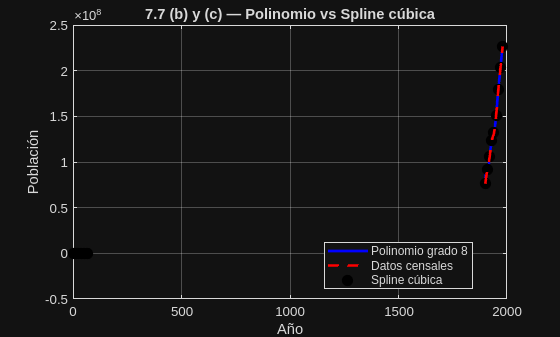

% Spline cúbica
y_spline = spline(t, y, t_anual);

% Agregar a la grafica anterior
figure(1)
plot(t_anual, y_spline, 'r--', 'LineWidth', 2)
legend('Polinomio grado 8', 'Datos censales', 'Spline cúbica')
title('7.7 (b) y (c) — Polinomio vs Spline cúbica')

**7.7** *(d)* — Extrapolación a 1990 con polinomio y spline

% Valor real del censo 1990
y_real_1990 = 248709873;

% Extrapolación con polinomio (Horner, base 4)
t_1990_transf = (1990 - 1940) / 40;
y_poly_1990 = horner_base4(c, t_1990_transf);

% Extrapolación con spline
y_spline_1990 = spline(t, y, 1990);

% Resultados
fprintf('Extrapolación a 1990:\n')

Extrapolación a 1990:


fprintf('  Valor real censo 1990  : %15.0f\n', y_real_1990)

  Valor real censo 1990  :       248709873


fprintf('  Polinomio grado 8      : %15.0f\n', y_poly_1990)

  Polinomio grado 8      :        82749141


fprintf('  Spline cúbica          : %15.0f\n', y_spline_1990)

  Spline cúbica          :       256915297


fprintf('\nErrores absolutos:\n')


Errores absolutos:


fprintf('  Error polinomio        : %15.0f\n', abs(y_poly_1990 - y_real_1990))

  Error polinomio        :       165960732


fprintf('  Error spline           : %15.0f\n', abs(y_spline_1990 - y_real_1990))

  Error spline           :         8205424


fprintf('\nErrores relativos:\n')


Errores relativos:


fprintf('  Error relativo polinomio : %.4f%%\n', abs(y_poly_1990 - y_real_1990)/y_real_1990*100)

  Error relativo polinomio : 66.7286%


fprintf('  Error relativo spline    : %.4f%%\n', abs(y_spline_1990 - y_real_1990)/y_real_1990*100)

  Error relativo spline    : 3.2992%


La extrapolación más allá del rango de datos es siempre riesgosa. El polinomio de grado alto tiende a oscilar bruscamente fuera del intervalo de interpolación, por lo que su extrapolación a 1990 puede ser muy imprecisa. La spline cúbica extrapola usando solo el último subintervalo [1970, 1980], lo que la hace más conservadora y generalmente más cercana al valor real.

7.7 (e) — Interpolante de Lagrange y comparación de tiempos de ejecución

% Evaluación con Lagrange
y_lagrange = zeros(size(t_anual));
for k = 1:length(t_anual)
    y_lagrange(k) = lagrange_interp(t, y, t_anual(k));
end

% Comparación de tiempos
n_rep = 1000;

% Tiempo Horner
t0 = tic;
for r = 1:n_rep
    for k = 1:length(t_anual)
        horner_base4(c, (t_anual(k)-1940)/40);
    end
end
tiempo_horner = toc(t0) / n_rep;

% Tiempo Spline
t0 = tic;
for r = 1:n_rep
    spline(t, y, t_anual);
end
tiempo_spline = toc(t0) / n_rep;

% Tiempo Lagrange
t0 = tic;
for r = 1:n_rep
    for k = 1:length(t_anual)
        lagrange_interp(t, y, t_anual(k));
    end
end
tiempo_lagrange = toc(t0) / n_rep;

fprintf('Tiempos promedio de evaluación (%d repeticiones):\n', n_rep)

Tiempos promedio de evaluación (1000 repeticiones):


fprintf('  Horner   : %.6f s\n', tiempo_horner)

  Horner   : 0.000057 s


fprintf('  Spline   : %.6f s\n', tiempo_spline)

  Spline   : 0.000288 s


fprintf('  Lagrange : %.6f s\n', tiempo_lagrange)

  Lagrange : 0.000076 s


fprintf('\nRatios respecto a Horner:\n')


Ratios respecto a Horner:


fprintf('  Spline / Horner   : %.2f\n', tiempo_spline   / tiempo_horner)

  Spline / Horner   : 5.08


fprintf('  Lagrange / Horner : %.2f\n', tiempo_lagrange / tiempo_horner)

  Lagrange / Horner : 1.33


Función auxiliar: interpolante de Lagrange

function p = lagrange_interp(t, y, x)
    n = length(t);
    p = 0;
    for i = 1:n
        L = 1;
        for j = 1:n
            if j ~= i
                L = L * (x - t(j)) / (t(i) - t(j));
            end
        end
        p = p + y(i) * L;
    end
end

Lagrange es el más lento porque para cada punto de evaluación recorre todos los nodos dos veces (bucle doble). Horner es el más rápido porque 

evalúa el polinomio en O(n) operaciones sin productos redundantes. La spline tiene un costo intermedio ya que primero localiza el subintervalo y luego evalúa un polinomio cúbico local.

**7.7** *(f)* — Forma de Newton del polinomio interpolante y agregado del punto 1990

% Coeficientes de Newton para los 9 puntos originales (1900-1980)
c_newton = newton_coeficientes(t, y);

fprintf('Coeficientes de Newton (grado 8):\n')

Coeficientes de Newton (grado 8):


for k = 1:length(c_newton)
    fprintf('  c(%d) = %15.6e\n', k, c_newton(k))
end

  c(1) =    7.621217e+07
  c(2) =    1.601633e+06
  c(3) =   -1.111643e+04
  c(4) =    9.352222e+02
  c(5) =   -7.174384e+01
  c(6) =    3.937011e+00
  c(7) =   -1.347935e-01
  c(8) =    3.078344e-03
  c(9) =   -4.809269e-05


Agregar el punto de 1990 sin recalcular desde cero

% Nuevo punto
t_1990 = 1990;
y_1990 = 248709873;

% Agregar punto usando la rutina de la parte 7.2 (b)
[c_newton9, t_newton9] = newton_agregar_punto(c_newton, t, t_1990, y_1990);

fprintf('Nuevo coeficiente agregado (grado 9):\n')

Nuevo coeficiente agregado (grado 9):


fprintf('  c(10) = %15.6e\n', c_newton9(end))

  c(10) =    4.573433e-07


Graficar ambos polinomios de Newton en [1900, 1990]

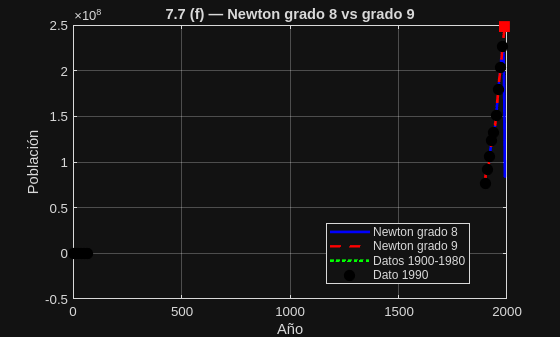

% Evaluación de ambos polinomios en intervalos anuales
t_rango = 1900:1:1990;

y_newton8 = zeros(size(t_rango));
y_newton9 = zeros(size(t_rango));

for k = 1:length(t_rango)
    y_newton8(k) = horner_newton(c_newton,  t,        t_rango(k));
    y_newton9(k) = horner_newton(c_newton9, t_newton9, t_rango(k));
end

% Grafica
figure(2)
plot(t_rango, y_newton8, 'b-',  'LineWidth', 2)
hold on
plot(t_rango, y_newton9, 'r--', 'LineWidth', 2)
plot(t, y, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k')
plot(t_1990, y_1990, 'rs', 'MarkerSize', 10, 'MarkerFaceColor', 'r')
xlabel('Año'); ylabel('Población')
title('7.7 (f) — Newton grado 8 vs grado 9')
legend('Newton grado 8', 'Newton grado 9', 'Datos 1900-1980', 'Dato 1990')
grid on

El polinomio de grado 9 pasa exactamente por el punto de 1990 al haberlo agregado como nodo de interpolación. Fuera de ese punto ambos polinomios 

coinciden en los nodos originales pero pueden diferir entre ellos, especialmente cerca de los extremos del intervalo donde los polinomios de grado alto tienden a oscilar. El método de Newton permite agregar el nuevo punto calculando solo un coeficiente adicional, sin rehacer todo el sistema.

7.7 (g) — Redondear datos al millón más cercano y comparar coeficientes

% Redondear al millón más cercano
y_redondeado = round(y / 1e6) * 1e6;

fprintf('Datos originales vs redondeados:\n')

Datos originales vs redondeados:


fprintf('  %-6s  %-15s  %-15s  %-12s\n', 'Año', 'Original', 'Redondeado', 'Diferencia')

  Año     Original         Redondeado       Diferencia  


for k = 1:length(t)
    fprintf('  %-6d  %-15.0f  %-15.0f  %-12.0f\n', ...
        t(k), y(k), y_redondeado(k), y(k) - y_redondeado(k))
end

  1900    76212168         76000000         212168      
  1910    92228496         92000000         228496      
  1920    106021537        106000000        21537       
  1930    123202624        123000000        202624      
  1940    132164569        132000000        164569      
  1950    151325798        151000000        325798      
  1960    179323175        179000000        323175      
  1970    203302031        203000000        302031      
  1980    226542199        227000000        -457801     


Resolver sistema con datos redondeados usando la misma base 4

% Resolver con base 4 y datos redondeados
c_redondeado = V4 \ y_redondeado';

fprintf('\nComparación de coeficientes (Base 4):\n')


Comparación de coeficientes (Base 4):


fprintf('  %-6s  %-20s  %-20s  %-12s\n', 'Coef.', 'Original', 'Redondeado', 'Diferencia')

  Coef.   Original              Redondeado            Diferencia  


for k = 1:length(c)
    fprintf('  c(%-2d)   %-20.6e  %-20.6e  %-12.6e\n', ...
        k, c(k), c_redondeado(k), abs(c(k) - c_redondeado(k)))
end

  c(1 )   1.321646e+08          1.320000e+08          1.645690e+05
  c(2 )   4.613077e+07          4.595714e+07          1.736227e+05
  c(3 )   1.027163e+08          1.001413e+08          2.575045e+06
  c(4 )   1.825271e+08          1.811111e+08          1.416019e+06
  c(5 )   -3.746147e+08         -3.567556e+08         1.785916e+07
  c(6 )   -3.426685e+08         -3.384889e+08         4.179567e+06
  c(7 )   6.062912e+08          5.703111e+08          3.598014e+07
  c(8 )   1.891756e+08          1.869206e+08          2.254941e+06
  c(9 )   -3.151802e+08         -2.941968e+08         2.098341e+07


Graficar ambos polinomios para comparar visualmente

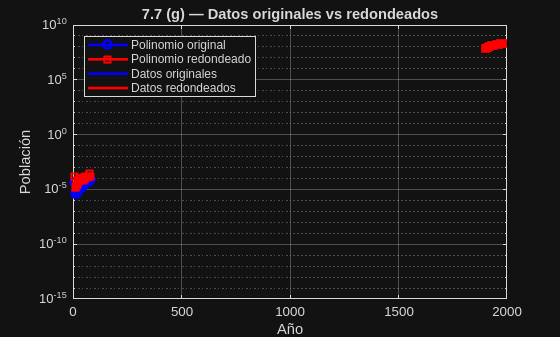

% Evaluar polinomio con coeficientes redondeados
y_horner_red = zeros(size(t_anual));
for k = 1:length(t_anual)
    y_horner_red(k) = horner_base4(c_redondeado, t_anual_transf(k));
end

figure(3)
plot(t_anual, y_horner,     'b-',  'LineWidth', 2)
hold on
plot(t_anual, y_horner_red, 'r--', 'LineWidth', 2)
plot(t, y,            'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k')
plot(t, y_redondeado, 'rs', 'MarkerSize', 8, 'MarkerFaceColor', 'r')
xlabel('Año'); ylabel('Población')
title('7.7 (g) — Datos originales vs redondeados')
legend('Polinomio original', 'Polinomio redondeado', ...
       'Datos originales', 'Datos redondeados')
grid on

Aunque el redondeo al millón más cercano parece una perturbación pequeña relativa a los datos (menos del 1%), los coeficientes del polinomio pueden 

cambiar significativamente. Esto ocurre porque la matriz de Vandermonde, aun con la base 4 bien condicionada, amplifica las perturbaciones en los 

datos al calcular los coeficientes. Este fenómeno ilustra que incluso errores de redondeo aparentemente pequeños en los datos pueden producir 

coeficientes muy distintos, aunque el polinomio resultante se vea visualmente similar en la gráfica.

# `Métodos-Numéricos-con-Matlab-John-H-Mathews`

### `Capítulo 7. Integración Numérica.`

- Integración numérica — Reglas de cuadratura (4)-(7)

Intervalo [a,b] = [0,1]

Funciones:

(a) f(x) = sin(pi*x)          exacto = 2/pi

(b) f(x) = 1 + exp(-x)*cos(4x)  exacto = (18e - cos(4) + 4*sin(4))/(17e)

(c) f(x) = sin(sqrt(x))       exacto = 2*(sin(1) - cos(1))

% Funciones
fa = @(x) sin(pi*x);
fb = @(x) 1 + exp(-x).*cos(4*x);
fc = @(x) sin(sqrt(x));

% Valores exactos
exact_a = 2/pi;
exact_b = (18*exp(1) - cos(4) + 4*sin(4)) / (17*exp(1));
exact_c = 2*(sin(1) - cos(1));

fprintf('Valores exactos:\n')

Valores exactos:


fprintf('  (a) %.11f\n', exact_a)

  (a) 0.63661977237


fprintf('  (b) %.11f\n', exact_b)

  (b) 1.00745963140


fprintf('  (c) %.11f\n', exact_c)

  (c) 0.60233735788


Regla del Trapecio (4) — h = 1

h = 1;
x = [0, 1];

trap_a = (h/2)*(fa(x(1)) + fa(x(2)));
trap_b = (h/2)*(fb(x(1)) + fb(x(2)));
trap_c = (h/2)*(fc(x(1)) + fc(x(2)));

fprintf('Trapecio (h=1):\n')

Trapecio (h=1):


fprintf('  (a) aprox=%.11f  error=%.4e\n', trap_a, abs(trap_a - exact_a))

  (a) aprox=0.00000000000  error=6.3662e-01


fprintf('  (b) aprox=%.11f  error=%.4e\n', trap_b, abs(trap_b - exact_b))

  (b) aprox=1.37976897502  error=3.7231e-01


fprintf('  (c) aprox=%.11f  error=%.4e\n', trap_c, abs(trap_c - exact_c))

  (c) aprox=0.42073549240  error=1.8160e-01


Regla de Simpson (5) — h = 1/2

h = 1/2;
x = [0, 1/2, 1];

simp_a = (h/3)*(fa(x(1)) + 4*fa(x(2)) + fa(x(3)));
simp_b = (h/3)*(fb(x(1)) + 4*fb(x(2)) + fb(x(3)));
simp_c = (h/3)*(fc(x(1)) + 4*fc(x(2)) + fc(x(3)));

fprintf('Simpson (h=1/2):\n')

Simpson (h=1/2):


fprintf('  (a) aprox=%.11f  error=%.4e\n', simp_a, abs(simp_a - exact_a))

  (a) aprox=0.66666666667  error=3.0047e-02


fprintf('  (b) aprox=%.11f  error=%.4e\n', simp_b, abs(simp_b - exact_b))

  (b) aprox=0.95831911480  error=4.9141e-02


fprintf('  (c) aprox=%.11f  error=%.4e\n', simp_c, abs(simp_c - exact_c))

  (c) aprox=0.57333645685  error=2.9001e-02


Regla 3/8 de Simpson (6) — h = 1/3

h = 1/4;
x = [0, 1/4, 1/2, 3/4, 1];

boole_a = (2*h/45)*(7*fa(x(1)) + 32*fa(x(2)) + 12*fa(x(3)) + 32*fa(x(4)) + 7*fa(x(5)));
boole_b = (2*h/45)*(7*fb(x(1)) + 32*fb(x(2)) + 12*fb(x(3)) + 32*fb(x(4)) + 7*fb(x(5)));
boole_c = (2*h/45)*(7*fc(x(1)) + 32*fc(x(2)) + 12*fc(x(3)) + 32*fc(x(4)) + 7*fc(x(5)));

fprintf('Boole (h=1/4):\n')

Boole (h=1/4):


fprintf('  (a) aprox=%.11f  error=%.4e\n', boole_a, abs(boole_a - exact_a))

  (a) aprox=0.63616482218  error=4.5495e-04


fprintf('  (b) aprox=%.11f  error=%.4e\n', boole_b, abs(boole_b - exact_b))

  (b) aprox=1.00876275978  error=1.3031e-03


fprintf('  (c) aprox=%.11f  error=%.4e\n', boole_c, abs(boole_c - exact_c))

  (c) aprox=0.59337640893  error=8.9609e-03


fprintf('  (a) aprox=%.11f  error=%.4e\n', s38_a, abs(s38_a - exact_a))

Unrecognized function or variable 's38_a'.

fprintf('  (b) aprox=%.11f  error=%.4e\n', s38_b, abs(s38_b - exact_b))
fprintf('  (c) aprox=%.11f  error=%.4e\n', s38_c, abs(s38_c - exact_c))

Resumen comparativo de errores

fprintf('\n%-20s %-14s %-14s %-14s\n', 'Regla', 'Error (a)', 'Error (b)', 'Error (c)')
fprintf('%s\n', repmat('-', 1, 62))
fprintf('%-20s %-14.4e %-14.4e %-14.4e\n', 'Trapecio',      abs(trap_a-exact_a), abs(trap_b-exact_b), abs(trap_c-exact_c))
fprintf('%-20s %-14.4e %-14.4e %-14.4e\n', 'Simpson',       abs(simp_a-exact_a), abs(simp_b-exact_b), abs(simp_c-exact_c))
fprintf('%-20s %-14.4e %-14.4e %-14.4e\n', 'Simpson 3/8',   abs(s38_a-exact_a),  abs(s38_b-exact_b),  abs(s38_c-exact_c))
fprintf('%-20s %-14.4e %-14.4e %-14.4e\n', 'Boole',         abs(boole_a-exact_a), abs(boole_b-exact_b), abs(boole_c-exact_c))